## Setting parameters for the simulation

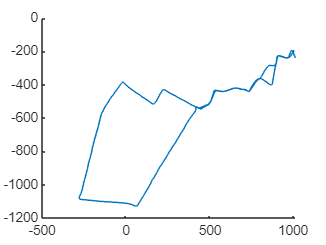

bikes = 1×2 cell array
    {1×1 bluetoothLENode}    {1×1 bluetoothLENode}


simulationTime = 839.9000

24-Jan-2025 19:52:18: Starting simulation
24-Jan-2025 20:09:32: Simulation ended

iteration = uint32
8401

global beginIteration
global endIteration
global newSimulation
global receivedData;
global iteration
newSimulation = true;

if newSimulation
    eventBased = true;
    beginIteration = 1;
    endIteration = height(bikeData{1});

    bikeData = loadBikeData();
    [newX, newY] = rotateCoordinates(bikeData{2}, -90);
    bikeData{2}.x = newX;
    bikeData{2}.y = newY;

    for i = 1:length(bikeData)
        bikeData{i}.("heading") = calculateHeading(bikeData{i});
        if eventBased
            bikeData{i}.toSend = determineEventBasedSending(bikeData{i});
        end
    end

    networkSimulator = wirelessNetworkSimulator.init;
    amountX = 3;
    amountY = 4;

    [grid, receivedData] = createGrid(amountX, amountY);
    bikes = setupBikes(grid)

    toReceive = determineToReceive(grid, bikeData);
    toReceive = [toReceive determineToReceiveBikes(bikes, bikeData, length(grid))];
    setListeners(grid, bikes);
   
    iteration = uint32(beginIteration);

    simulationData = struct;
    simulationData.bikeData = bikeData;
    simulationData.simulator = networkSimulator;
    simulationData.bikes = bikes;
    simulationData.traffic = traffic;
    addNodes(networkSimulator, grid);
    addNodes(networkSimulator, bikes);
    bikeStats = runSimulation(networkSimulator, simulationData);


    simulationTime = datetime;
    if eventBased
        save("Output\results\event_based_simulation_" + strrep(string(simulationTime), ":", ".") + ".mat")
    else
        save("Output\results\periodic_based_simulation_" + strrep(string(simulationTime), ":", ".") + ".mat")
    end
else
    % load("Output\results\periodic_based_simulation_18-Jan-2025 23.48.43.mat"); % Data of period transmissions used for the paper
    load("Output\results\event_based_simulation_19-Jan-2025 13.01.22.mat"); % Data of event-triggered transmissions used for the paper
    newSimulation = false;
end

## Calculating package delivery ratio

fprintf("Node\tExpected\tReceived\tRatio")

Node	Expected	Received	Ratio

for i = 1:length(grid)
    [expected, received, ratio] = calculatePacketDeliveryRatio(grid{i}, toReceive{i});

    if ~isnan(expected)
        fprintf("%s:\t%d\t%d\t%.4f\n", grid{i}.Name, expected, received, ratio)
    end
end

Grid1:	72	67	0.9306
Grid5:	8	7	0.8750
Grid6:	50	50	1.0000
Grid8:	102	101	0.9902
Grid10:	108	101	0.9352
Grid14:	57	53	0.9298
Grid16:	31	31	1.0000
Grid17:	18	18	1.0000
Grid18:	26	23	0.8846
Grid19:	28	28	1.0000
Grid20:	38	38	1.0000


## Calculating MSE's

calculatedPositions = dictionary;

if ~eventBased % With the messages used for event-triggered broadcasting every
    % 10 data-rows are compared to the predicted locations, so each
    % prediction is only checked once instead of 10 times. Note that this
    % only works due to the fact that the location changes every 10 data-rows
    for i = 1:length(bikeData)
        bikeData{i}.toSend = determineEventBasedSending(bikeData{i});
    end
    
    toReceive = determineToReceive(grid, bikeData);
end

for i=1:length(grid)
    if ~isempty(receivedData{grid{i}.Name})
        receivedBikes = unique(receivedData{grid{i}.Name}(1, :));
        receivedBikes = receivedBikes(receivedBikes <= length(grid) + length(bikes));
        
        calculatedPositions{grid{i}.Name} = dictionary;
        for bike = receivedBikes
            dataReceived = [];

            for j = 1:length(receivedData{grid{i}.Name})
                if receivedData{grid{i}.Name}(1, j) == bike
                    dataReceived(end+1) = receivedData{grid{i}.Name}(2, j);
                end
            end

            dataExpected = [];

            for j = 1:length(toReceive{i})
                if toReceive{i}(1, j) == bike
                    dataExpected(end+1) = toReceive{i}(2, j);
                end
            end

            if ~isempty(dataExpected)
                calculatedPositions{grid{i}.Name}{bike} = calculatePositions(dataReceived, ...
                    dataExpected, bikeData{bike - length(grid)}, grid{i});
            end
        end
    end
end

for node=keys(calculatedPositions)'
    for bike = keys(calculatedPositions{node})'
        meanSquaredError = 0;
        for i = keys(calculatedPositions{node}{bike})'
            position = calculatedPositions{node}{bike}{i};
            meanSquaredError = meanSquaredError + ((bikeData{bike-length(grid)}.x(i) - position(1))^2 + ...
                (bikeData{bike-length(grid)}.y(i) - position(2))^2);
        end
        meanSquaredError = meanSquaredError/length(keys(calculatedPositions{node}{bike}));

        fprintf("Mean-Squared error for %s Bike%i: %.4f\n", node, bike - length(grid), meanSquaredError)
    end
end

Mean-Squared error for Grid1 Bike1: 5.4426
Mean-Squared error for Grid5 Bike2: 6.2726
Mean-Squared error for Grid6 Bike1: 0.0015
Mean-Squared error for Grid8 Bike2: 0.0293
Mean-Squared error for Grid10 Bike1: 0.5396
Mean-Squared error for Grid10 Bike2: 0.0198
Mean-Squared error for Grid14 Bike1: 0.0587
Mean-Squared error for Grid14 Bike2: 0.0000
Mean-Squared error for Grid16 Bike1: 0.0000
Mean-Squared error for Grid17 Bike2: 0.0000
Mean-Squared error for Grid18 Bike1: 1.2027
Mean-Squared error for Grid19 Bike1: 0.0000
Mean-Squared error for Grid20 Bike1: 0.0007


## Display calculated positions

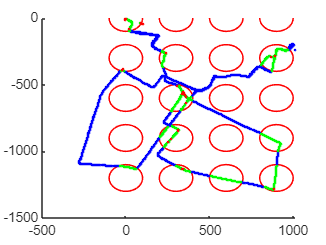

figure

function plotOriginalData(bikeData)
    toPlotX = [bikeData.x(1)];
    toPlotY = [bikeData.y(1)];
    for i = 2:height(bikeData)
        if bikeData.x(i) ~= bikeData.x(i-1) || bikeData.y(i) ~= bikeData.y(i-1)
            toPlotX(end+1) = bikeData.x(i);
            toPlotY(end+1) = bikeData.y(i);
        end
    end
    scatter(toPlotX, toPlotY, 3, "filled", MarkerFaceColor="blue")
end

hold on
for i=1:length(grid)
    circle(grid{i}.Position(1), grid{i}.Position(2), 100);
end

for i = 1:length(bikeData)
    plotOriginalData(bikeData{i})
end

for node=keys(calculatedPositions)'
    for bike = keys(calculatedPositions{node})'
        positions = cell2mat(values(calculatedPositions{node}{bike}))';

        positionsReceivedX = [];
        positionsReceivedY = [];
        positionsCalculatedX = [];
        positionsCalculatedY = [];

        for i = 1:length(positions)
            if positions(3, i)
                positionsReceivedX(end+1) = positions(1, i);
                positionsReceivedY(end+1) = positions(2, i);
            else
                positionsCalculatedX(end+1) = positions(1, i);
                positionsCalculatedY(end+1) = positions(2, i);
            end
        end

        scatter(positionsReceivedX, positionsReceivedY, 3, "filled", MarkerFaceColor="green")
        scatter(positionsCalculatedX, positionsCalculatedY, 3, "filled", MarkerFaceColor="red")
    end
end
hold off


% Saving the figure for use in latex
if newSimulation
    cleanfigure();
    if eventBased
        matlab2tikz('Output\figures\event-based predictions' + strrep(string(simulationTime), ":", ".") + '.tex')
    else
        matlab2tikz('Output\figures\periodic predictions' + strrep(string(simulationTime), ":", ".") + '.tex')
    end
end

Error using m2tInputParser>parse (line 182)
m2tInputParser: invalid input

Error in matlab2tikz (

## Load data

function bikeData = loadBikeData()
    dataPath = fullfile("Data/location_data (1)");
    dataDirectory = dir(dataPath);
    bikeData = [];
    
    for i = 3:4 % The first to paths point to the directory itself and the top directory
        baseFileName = dataDirectory(i).name;
        fullFileName = fullfile(dataPath, baseFileName);
        table = readtable(fullFileName);
        bikeData{end+1} = table(:, [2, 5:15, 17]);
    end
    
    for i = 1:length(bikeData)
        bikeData{i}.("toSend") = true(height(bikeData{i}), 1);
    end

    % Calculating cartesian coordinates
    altitude = 30;  % 30 meters is an approximate altitude in Enschede
    origin = [bikeData{1}.latitude(1), bikeData{1}.longitude(1), altitude];
    for i = 1:length(bikeData)
        [x, y] = calculateCartesianCoordinates(bikeData{i}, origin, altitude);
        bikeData{i}.("x") = x;
        bikeData{i}.("y") = y;
    end
end

Now, the GPS coordinates are converted to (x, y) coordinates.

## Calculating Cartesian coordinates from GPS data and rotating bike paths

function [x, y] = calculateCartesianCoordinates(bikeData, origin, altitude)
    % altitude = 30;  % 30 meters is an approximate altitude in Enschede
    [x,y] = latlon2local(bikeData.latitude, bikeData.longitude, altitude, origin);
end

function [x, y] = rotateCoordinates(bikeData, angle)
    newCoordinates = line(bikeData.x, bikeData.y);
    rotate(newCoordinates, [0 0 1], angle);
    x = transpose(newCoordinates.XData);
    y = transpose(newCoordinates.YData);
end

figure

hold on
for i = 1:length(bikeData)
    plot(bikeData{i}.x, bikeData{i}.y)
end


function headings = calculateHeading(bikeData)
    headings = zeros(height(bikeData), 1);
    for j = 2:height(bikeData)
        currentPos = table2array(bikeData(j, ["x", "y"]));
        previousPos = table2array(bikeData(j-1, ["x", "y"]));
        if currentPos ~= previousPos
            heading = [currentPos(1) - previousPos(1), ...
                currentPos(2) - previousPos(2)];
            headings(j) = rad2deg(atan2(heading(2), heading(1)));
        else
            headings(j) = headings(j-1);
        end
    end
end

## Creating grid of listener nodes

function [nodes, receivedData] = createGrid(amountX, amountY)
    distance = 300;
    nodes = [];
    storageArray = [];
    nodeNames = string;
    nodeID = 1;

    for y = 0:distance:amountY*distance
        for x = 0:distance:amountX*distance
            config = bluetoothMeshProfileConfig(ElementAddress=dec2hex(nodeID,4),...
                NetworkTransmissions=1);
            node = bluetoothLENode("broadcaster-observer", Name="Grid" + nodeID);
            node.Position = [x -y 0];
            nodes{end+1} = node;
            storageArray{nodeID} = uint32.empty(2, 0);
            nodeNames(nodeID) = node.Name;
            nodeID = nodeID + 1;
        end
    end

   receivedData = dictionary(nodeNames, storageArray);
end

function h = circle(x,y,r)
    drawcircle(Center=[x, y], Radius=r, Color='red', InteractionsAllowed='none', FaceAlpha=0, LineWidth=1);
end

for i=1:length(grid)
    circle(grid{i}.Position(1), grid{i}.Position(2), 100);
end
hold off

## Determining which messages to send

function toSend = determineEventBasedSending(bikeData)
    global beginIteration
    global endIteration

    maxGenerateTime = 5000; % the maximum time between two transmitted messages, which is 5000 ms
    minDistance = 4; % minimum change in distance after last transmitted message, which is 4 meters
    minSpeedChange = 5; % minimum speed change between after last transmitted message, which is 5 m/s
    minheadingChange = 4; % minimum change in heading after last transmitted message, which is 4 degrees
    
    toSend = bikeData.toSend;
    
    lastMessage = beginIteration;
    
    for i = beginIteration:endIteration
        if bikeData.timestamp_ms(i) >= bikeData.timestamp_ms(lastMessage) + maxGenerateTime
            lastMessage = i;
            toSend(i) = true;
        elseif pdist2(bikeData{i, ["x" "y"]}, bikeData{lastMessage, ["x" "y"]}) >= minDistance
            lastMessage = i;
            toSend(i) = true;
        elseif abs(bikeData.velocity(i) - bikeData.velocity(lastMessage))/3.6 >= minSpeedChange
            lastMessage = i;
            bikeData.toSend(i) = true;
        elseif abs(bikeData.heading(i) - bikeData.heading(lastMessage)) >= minheadingChange
            lastMessage = i;
            toSend(i) = true;
        else
            toSend(i) = false;
        end
    end
end



## Determine which messages each listener node should receive

function x = inRange(position1, position2)
    distance = pdist2(position1, position2);
    x = distance < 100;
end

function toReceive = determineToReceive(grid, bikeData)
    global beginIteration
    global endIteration
        
    for k = 1:length(grid)
        toReceive{k} = uint32.empty(2, 0);
        for i = 1:length(bikeData)
            for j = beginIteration:endIteration
                messagePosition = [bikeData{i}.x(j) bikeData{i}.y(j)];
                if (inRange(grid{k}.Position([1 2]), messagePosition)) && (bikeData{i}.toSend(j))
                    toReceive{k}(:, end + 1) = [uint32(length(grid) + i) uint32(j)];
                end
            end
        end
    end
end

function toReceive = determineToReceiveBikes(bikes, bikeData, gridLength)
    global beginIteration
    global endIteration

    for k = 1:length(bikes)
        toReceive{k} = uint32.empty(2, 0);
        for i = 1:length(bikeData)
            if i ~= k
                for j = beginIteration:endIteration
                    position1 = [bikeData{k}.x(j) bikeData{k}.y(j)];
                    position2 = [bikeData{i}.x(j) bikeData{i}.y(j)];
                    if inRange(position1, position2) && bikeData{i}.toSend(j)
                        toReceive{k}(:, end + 1) = [uint32(gridLength + i) uint32(j)];
                    end
                end
            end
        end
    end
end


## Setup simulation

function bikes = setupBikes(grid)
    global receivedData
    config = bluetoothMeshProfileConfig(ElementAddress=dec2hex(length(grid)+1, 4),...
            NetworkTransmissions=1, Relay=false);
    
    bike1 = bluetoothLENode("broadcaster-observer", Name="Bike1", MeshConfig=config);
    bike2 = bluetoothLENode("broadcaster-observer", Name="Bike2", MeshConfig=config);
    
    receivedData(bike1.Name) = {uint32.empty(2, 0)};
    receivedData(bike2.Name) = {uint32.empty(2, 0)};
    
    bikes = {bike1 bike2};
        
    global traffic
    traffic = dictionary;
    
    for i = 1:length(bikes)
        traffic{bikes{i}.Name} = networkTrafficOnOff(OnTime=0.02, OffTime=0.08, PacketSize=8, GeneratePacket=true, DataRate=10);
        addTrafficSource(bikes{i}, traffic{bikes{i}.Name}, ...
            SourceAddress=bikes{i}.MeshConfig.ElementAddress, ...
            DestinationAddress=grid{5}.MeshConfig.ElementAddress);
    end
end

Create listener to process received data

function processData(Node, EventData)
    global receivedData;
    message = EventData.Data.Message;

    received_id = typecast(uint8(transpose(message)), 'uint32');
    receivedData{Node.Name}(:, end+1) = received_id;
end

function setListeners(grid, bikes)
    for i = 1:length(grid)
        addlistener(grid{i}, "MeshAppDataReceived", @processData);
    end
    
    for i = 1:length(bikes)
        addlistener(bikes{i}, "MeshAppDataReceived", @processData);
    end
end

Create function which sets position of the bike 

function sendData(~, userData)
    global iteration;

    for i = 1:(length(userData.bikes))
        if userData.bikeData{i}.toSend(iteration)
            userData.bikes{i}.Position = [userData.bikeData{i}.x(iteration) ...
                userData.bikeData{i}.y(iteration) 0];
            
            bytes = typecast([userData.bikes{i}.ID iteration], "uint8");
            userData.traffic{userData.bikes{i}.Name}.ApplicationData = bytes;
            userData.traffic{userData.bikes{i}.Name}.OffTime = 0;
        else
            userData.traffic{userData.bikes{i}.Name}.OffTime = ...
                userData.traffic{userData.bikes{i}.Name}.OffTime + 0.1;
        end
    end
    
    iteration = iteration + 1;
end

Bluetooth messages will now be simulated

## Run simulation

function stats = runSimulation(networkSimulator, simulationData)
    global beginIteration
    global endIteration
    global iteration
    global receivedData

    scheduleAction(networkSimulator, @sendData, simulationData, 0, 0.1);

    simulationTime = (endIteration - beginIteration) / 10
    startTime = datetime;
    fprintf("%s: Starting simulation\n", startTime)
    run(networkSimulator,simulationTime);
    endTime = datetime;
    fprintf("%s: Simulation ended", endTime)
    iteration

    stats = [];
    for i=1:length(networkSimulator.Nodes)
        stats{i} = statistics(networkSimulator.Nodes{i});
    end
end

function [expected, correctlyReceived, fractionCorrect] = calculatePacketDeliveryRatio(node, expectedMessages)
    global receivedData
    totalReceived = 0;
    totalExpected = 0;

    expected = NaN;
    correctlyReceived = NaN;
    fractionCorrect = NaN;

        if length(expectedMessages) >= 1
            received = unique(receivedData{node.Name}.', "rows").';
            correctlyReceived = 0;
            expected = length(expectedMessages);
        
            for j=1:length(expectedMessages)
                if ismember(expectedMessages(:, j)', receivedData{node.Name}', "rows")
                    correctlyReceived = correctlyReceived + 1;
                end
            end
            
            correctlyReceived;
            fractionCorrect = correctlyReceived/length(expectedMessages);

            totalReceived = totalReceived + correctlyReceived;
            totalExpected = totalExpected + length(expectedMessages);
        end
    
    totalFractionCorrect = totalReceived/totalExpected;
end

## Calculate next position

function [x, y] = getNextPosition(previousPostition, speed, heading, duration)
    if nargin <= 3
        duration = 1;
    end
    distanceMoved = (speed/3.6)*duration;
    x = previousPostition(1) + distanceMoved * cosd(heading);
    y = previousPostition(2) + distanceMoved * sind(heading);
end

function calculatedPositions = calculatePositions(receivedMessages, expectedMessages, bikeData, node)
    calculatedPositions = dictionary;
    lastPosition = bikeData{expectedMessages(1), ["x" "y"]};
    speed = bikeData.velocity(expectedMessages(1));
    heading = bikeData.heading(expectedMessages(1));

    i = expectedMessages(1);
    index = 2;
    
    while i < expectedMessages(end)

        if ismember(i, receivedMessages)
            lastPosition = [bikeData{i, ["x" "y"]} true];
            speed = bikeData.velocity(i);
            heading = bikeData.heading(i);
        else
            [x, y] = getNextPosition(lastPosition, speed, heading);
            lastPosition = [x, y, false];
        end
        calculatedPositions{i} = lastPosition;
        
        
        if expectedMessages(index) <= i + 10
            i = expectedMessages(index);
            index = index + 1;
        elseif inRange(bikeData{i + 10, ["x" "y"]}, node.Position(1:2))
            i = i + 10;
        else
            i = expectedMessages(index);
            index = index + 1;
        end
    end
end